timems = loco(:,1)

timems = 252898×1 table
    Timems
    ______

       0  
       1  
       2  
       3  
       4  
       5  
       6  
       7  
       8  
       9  
      10  
      11  
      12  
      13  
      14  
      15  


locov = loco(:,2)

locov = 252898×1 table
    AI5_violet
    __________

      3.9854  
      3.9856  
      3.9857  
      3.9851  
       3.985  
      3.9848  
      3.9853  
      3.9854  
      3.9851  
      3.9856  
      3.9856  
      3.9851  
      3.9851  
      3.9854  
      3.9854  
      3.9848  


locoa = table2array(loco)

locoa = 	1.0e+05 *

         0    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0001    0.0000
    0.0001    0.0000
    0.0001    0.0000
    0.0001    0.0000
    0.0001    0.0000


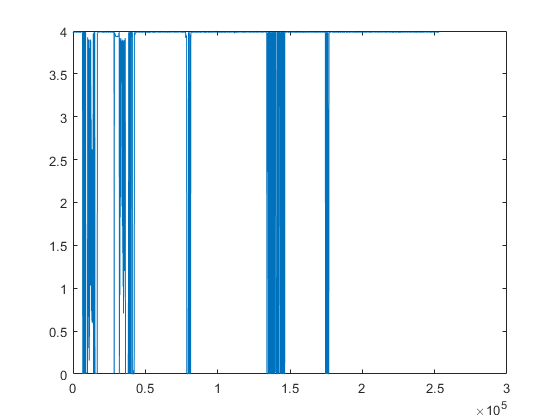

plot (locoa(:,1), locoa(:,2))

### Extract Velocity v26.a

%% velocity
% Define Wheel Statistics
Radius  = 11.06; %radus in cm
noftabs = 30; %number of tabs
circumference = 2*pi*Radius;
distpertab =circumference/(2*noftabs); %distance per tab (tabs are evenly spaced and the wheel is split equally)
samplerate = 1000; %aquisition rate
twindow = samplerate; %window in miliseconds

opto = locoa(:,2)

opto =     3.9854
    3.9856
    3.9857
    3.9851
    3.9850
    3.9848
    3.9853
    3.9854
    3.9851
    3.9856


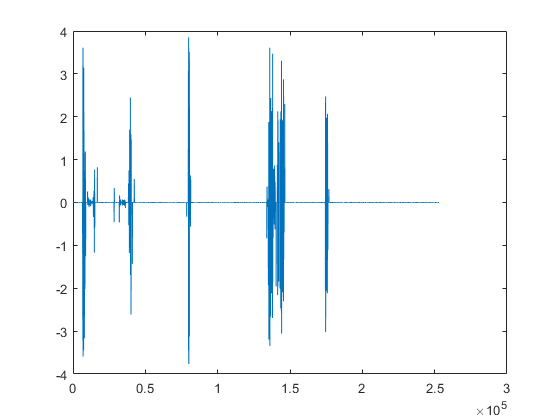


%Look at derivative of wheel trace
diffSC = diff(opto); %derivative of the square pulses
figure; plot(1:1:length(opto)-1,diffSC) %plot

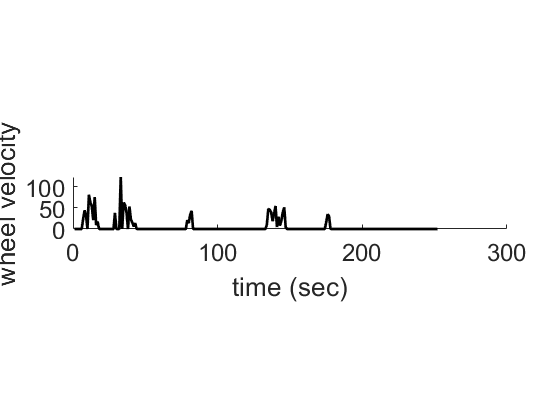


%define likely break points and binarize
triggerframes = find(abs(diffSC)>=mean(diffSC)+std(diffSC)); %find where there was probably a change from blocked to open
tabtransittimes = zeros(1,length(opto)); %make an empty matrix
tabtransittimes(triggerframes)= 1; %binarize the transitions

%sum transitions over the window
j=1;
for i=1:twindow:length(opto)-twindow
    numbreaks(j) = sum(tabtransittimes(i:i+twindow));
    j=j+1;
end

velocity = numbreaks * distpertab; %gives approximate velocity at ege of wheel
burstStats.velocity = velocity;

figure; hold on;
subplot(5,1,3); hold on;
plot(1:length(numbreaks),velocity, 'LineWidth',2,'Color','k')
ylabel('wheel velocity')
xlabel('time (sec)')
set(gca,'FontSize',18)

%axis([0 length(epercEvts) 0 max(velocity)+5])

Unrecognized function or variable 'epercEvts'.

### Extract pupil v26.a

Pupildata

length(Pupildata)

ans = 7588

v26a.pupil = zeros(length(Pupildata), 1)

v26a = struct with fields:
    pupil: [7588×1 double]


v26a.pupil

ans =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


Pupildata{1,900}

ans = struct with fields:
       rotated_rect: [20.1855 39.4827 40.9740 48.0589 13.9017]
             center: [279.1855 142.4827]
            major_r: 48.0589
           frame_id: 900
    frame_intensity: 18.5673
            contour: [54×1×2 int16]


isfield(Pupildata{1,3105}, 'frame_id')

ans = logical
   1


isfield(Pupildata{1,3105}, 'major_r')

ans = logical
   1


for ii = 1:length(Pupildata)
    %disp(ii)
    if isfield(Pupildata{1,ii}, 'major_r') == 0
        sprintf('major_r not found at index %d', ii)
        continue
    end
    v26a.pupil(ii) = Pupildata{1,ii}.major_r;
end

ans = 'major_r not found at index 7123'

ans = 'major_r not found at index 7124'

ans = 'major_r not found at index 7125'

ans = 'major_r not found at index 7128'

ans = 'major_r not found at index 7129'

ans = 'major_r not found at index 7130'

ans = 'major_r not found at index 7133'

ans = 'major_r not found at index 7134'

ans = 'major_r not found at index 7135'

ans = 'major_r not found at index 7137'

ans = 'major_r not found at index 7138'

ans = 'major_r not found at index 7139'

ans = 'major_r not found at index 7140'

ans = 'major_r not found at index 7142'

ans = 'major_r not found at index 7143'

ans = 'major_r not found at index 7146'

ans = 'major_r not found at index 7147'

ans = 'major_r not found at index 7149'

ans = 'major_r not found at index 7150'

ans = 'major_r not found at index 7152'

ans = 'major_r not found at index 7153'

ans = 'major_r not found at index 7154'

ans = 'major_r not found at index 7156'

ans = 'major_r not found at index 7157'

ans = 'major_r not found at index 7159'

ans = 'major_r not found at index 7160'

ans = 'major_r not found at index 7161'

ans = 'major_r not found at index 7162'

ans = 'major_r not found at index 7163'

ans = 'major_r not found at index 7165'

ans = 'major_r not found at index 7166'

ans = 'major_r not found at index 7168'

ans = 'major_r not found at index 7170'

ans = 'major_r not found at index 7171'

ans = 'major_r not found at index 7174'

ans = 'major_r not found at index 7175'

ans = 'major_r not found at index 7176'

ans = 'major_r not found at index 7178'

ans = 'major_r not found at index 7179'

ans = 'major_r not found at index 7180'

ans = 'major_r not found at index 7181'

ans = 'major_r not found at index 7182'

ans = 'major_r not found at index 7183'

ans = 'major_r not found at index 7184'

ans = 'major_r not found at index 7185'

ans = 'major_r not found at index 7187'

ans = 'major_r not found at index 7188'

ans = 'major_r not found at index 7189'

ans = 'major_r not found at index 7191'

ans = 'major_r not found at index 7193'

ans = 'major_r not found at index 7194'

ans = 'major_r not found at index 7195'

ans = 'major_r not found at index 7196'

ans = 'major_r not found at index 7197'

ans = 'major_r not found at index 7198'

ans = 'major_r not found at index 7199'

ans = 'major_r not found at index 7200'

ans = 'major_r not found at index 7201'

ans = 'major_r not found at index 7203'

ans = 'major_r not found at index 7204'

ans = 'major_r not found at index 7205'

ans = 'major_r not found at index 7206'

ans = 'major_r not found at index 7207'

ans = 'major_r not found at index 7208'

ans = 'major_r not found at index 7209'

ans = 'major_r not found at index 7211'

ans = 'major_r not found at index 7212'

ans = 'major_r not found at index 7213'

ans = 'major_r not found at index 7215'

ans = 'major_r not found at index 7216'

ans = 'major_r not found at index 7217'

ans = 'major_r not found at index 7218'

ans = 'major_r not found at index 7219'

ans = 'major_r not found at index 7220'

ans = 'major_r not found at index 7222'

ans = 'major_r not found at index 7223'

ans = 'major_r not found at index 7224'

ans = 'major_r not found at index 7225'

ans = 'major_r not found at index 7226'

ans = 'major_r not found at index 7228'

ans = 'major_r not found at index 7229'

ans = 'major_r not found at index 7230'

ans = 'major_r not found at index 7231'

ans = 'major_r not found at index 7232'

ans = 'major_r not found at index 7233'

ans = 'major_r not found at index 7235'

ans = 'major_r not found at index 7236'

ans = 'major_r not found at index 7237'

ans = 'major_r not found at index 7238'

ans = 'major_r not found at index 7239'

ans = 'major_r not found at index 7240'

ans = 'major_r not found at index 7241'

ans = 'major_r not found at index 7243'

ans = 'major_r not found at index 7244'

ans = 'major_r not found at index 7245'

ans = 'major_r not found at index 7246'

ans = 'major_r not found at index 7247'

ans = 'major_r not found at index 7248'

ans = 'major_r not found at index 7249'

ans = 'major_r not found at index 7251'

ans = 'major_r not found at index 7252'

ans = 'major_r not found at index 7253'

ans = 'major_r not found at index 7254'

ans = 'major_r not found at index 7255'

ans = 'major_r not found at index 7256'

ans = 'major_r not found at index 7257'

ans = 'major_r not found at index 7259'

ans = 'major_r not found at index 7260'

ans = 'major_r not found at index 7261'

ans = 'major_r not found at index 7262'

ans = 'major_r not found at index 7264'

ans = 'major_r not found at index 7265'

ans = 'major_r not found at index 7266'

ans = 'major_r not found at index 7267'

ans = 'major_r not found at index 7268'

ans = 'major_r not found at index 7269'

ans = 'major_r not found at index 7270'

ans = 'major_r not found at index 7271'

ans = 'major_r not found at index 7273'

ans = 'major_r not found at index 7274'

ans = 'major_r not found at index 7276'

ans = 'major_r not found at index 7277'

ans = 'major_r not found at index 7278'

ans = 'major_r not found at index 7280'

ans = 'major_r not found at index 7281'

ans = 'major_r not found at index 7282'

ans = 'major_r not found at index 7283'

ans = 'major_r not found at index 7284'

ans = 'major_r not found at index 7286'

ans = 'major_r not found at index 7287'

ans = 'major_r not found at index 7288'

ans = 'major_r not found at index 7290'

ans = 'major_r not found at index 7291'

ans = 'major_r not found at index 7293'

ans = 'major_r not found at index 7294'

ans = 'major_r not found at index 7295'

ans = 'major_r not found at index 7296'

ans = 'major_r not found at index 7297'

ans = 'major_r not found at index 7298'

ans = 'major_r not found at index 7299'

ans = 'major_r not found at index 7300'

ans = 'major_r not found at index 7302'

ans = 'major_r not found at index 7303'

ans = 'major_r not found at index 7304'

ans = 'major_r not found at index 7305'

ans = 'major_r not found at index 7306'

ans = 'major_r not found at index 7308'

ans = 'major_r not found at index 7309'

ans = 'major_r not found at index 7311'

ans = 'major_r not found at index 7312'

ans = 'major_r not found at index 7314'

ans = 'major_r not found at index 7317'

ans = 'major_r not found at index 7318'

ans = 'major_r not found at index 7319'

ans = 'major_r not found at index 7320'

ans = 'major_r not found at index 7321'

ans = 'major_r not found at index 7323'

ans = 'major_r not found at index 7325'

ans = 'major_r not found at index 7326'

ans = 'major_r not found at index 7327'

ans = 'major_r not found at index 7328'

ans = 'major_r not found at index 7330'

ans = 'major_r not found at index 7331'

ans = 'major_r not found at index 7333'

ans = 'major_r not found at index 7336'

ans = 'major_r not found at index 7337'

ans = 'major_r not found at index 7338'

ans = 'major_r not found at index 7340'

ans = 'major_r not found at index 7341'

ans = 'major_r not found at index 7342'

ans = 'major_r not found at index 7343'

ans = 'major_r not found at index 7345'

ans = 'major_r not found at index 7346'

ans = 'major_r not found at index 7348'

ans = 'major_r not found at index 7349'

ans = 'major_r not found at index 7350'

ans = 'major_r not found at index 7351'

ans = 'major_r not found at index 7353'

ans = 'major_r not found at index 7354'

ans = 'major_r not found at index 7355'

ans = 'major_r not found at index 7357'

ans = 'major_r not found at index 7358'

ans = 'major_r not found at index 7359'

ans = 'major_r not found at index 7360'

ans = 'major_r not found at index 7361'

ans = 'major_r not found at index 7363'

ans = 'major_r not found at index 7364'

ans = 'major_r not found at index 7365'

ans = 'major_r not found at index 7366'

ans = 'major_r not found at index 7367'

ans = 'major_r not found at index 7368'

ans = 'major_r not found at index 7369'

ans = 'major_r not found at index 7370'

ans = 'major_r not found at index 7372'

ans = 'major_r not found at index 7373'

ans = 'major_r not found at index 7374'

ans = 'major_r not found at index 7376'

ans = 'major_r not found at index 7377'

ans = 'major_r not found at index 7378'

ans = 'major_r not found at index 7380'

ans = 'major_r not found at index 7381'

ans = 'major_r not found at index 7382'

ans = 'major_r not found at index 7383'

ans = 'major_r not found at index 7386'

ans = 'major_r not found at index 7387'

ans = 'major_r not found at index 7388'

ans = 'major_r not found at index 7390'

ans = 'major_r not found at index 7391'

ans = 'major_r not found at index 7392'

ans = 'major_r not found at index 7393'

ans = 'major_r not found at index 7394'

ans = 'major_r not found at index 7395'

ans = 'major_r not found at index 7396'

ans = 'major_r not found at index 7397'

ans = 'major_r not found at index 7398'

ans = 'major_r not found at index 7400'

ans = 'major_r not found at index 7401'

ans = 'major_r not found at index 7402'

ans = 'major_r not found at index 7403'

ans = 'major_r not found at index 7404'

ans = 'major_r not found at index 7405'

ans = 'major_r not found at index 7406'

ans = 'major_r not found at index 7408'

ans = 'major_r not found at index 7409'

ans = 'major_r not found at index 7410'

ans = 'major_r not found at index 7411'

ans = 'major_r not found at index 7413'

ans = 'major_r not found at index 7415'

ans = 'major_r not found at index 7417'

ans = 'major_r not found at index 7418'

ans = 'major_r not found at index 7419'

ans = 'major_r not found at index 7420'

ans = 'major_r not found at index 7422'

ans = 'major_r not found at index 7423'

ans = 'major_r not found at index 7424'

ans = 'major_r not found at index 7426'

ans = 'major_r not found at index 7427'

ans = 'major_r not found at index 7428'

ans = 'major_r not found at index 7429'

ans = 'major_r not found at index 7430'

ans = 'major_r not found at index 7432'

ans = 'major_r not found at index 7433'

ans = 'major_r not found at index 7434'

ans = 'major_r not found at index 7436'

ans = 'major_r not found at index 7437'

ans = 'major_r not found at index 7438'

ans = 'major_r not found at index 7439'

ans = 'major_r not found at index 7440'

ans = 'major_r not found at index 7441'

ans = 'major_r not found at index 7442'

ans = 'major_r not found at index 7443'

ans = 'major_r not found at index 7444'

ans = 'major_r not found at index 7445'

ans = 'major_r not found at index 7447'

ans = 'major_r not found at index 7448'

ans = 'major_r not found at index 7450'

ans = 'major_r not found at index 7451'

ans = 'major_r not found at index 7452'

ans = 'major_r not found at index 7453'

ans = 'major_r not found at index 7454'

ans = 'major_r not found at index 7455'

ans = 'major_r not found at index 7456'

ans = 'major_r not found at index 7458'

ans = 'major_r not found at index 7459'

ans = 'major_r not found at index 7461'

ans = 'major_r not found at index 7462'

ans = 'major_r not found at index 7463'

ans = 'major_r not found at index 7464'

ans = 'major_r not found at index 7465'

ans = 'major_r not found at index 7466'

ans = 'major_r not found at index 7467'

ans = 'major_r not found at index 7468'

ans = 'major_r not found at index 7469'

ans = 'major_r not found at index 7471'

ans = 'major_r not found at index 7472'

ans = 'major_r not found at index 7473'

ans = 'major_r not found at index 7475'

ans = 'major_r not found at index 7476'

ans = 'major_r not found at index 7477'

ans = 'major_r not found at index 7478'

ans = 'major_r not found at index 7480'

ans = 'major_r not found at index 7481'

ans = 'major_r not found at index 7482'

ans = 'major_r not found at index 7484'

ans = 'major_r not found at index 7485'

ans = 'major_r not found at index 7486'

ans = 'major_r not found at index 7487'

ans = 'major_r not found at index 7489'

ans = 'major_r not found at index 7490'

ans = 'major_r not found at index 7492'

ans = 'major_r not found at index 7493'

ans = 'major_r not found at index 7494'

ans = 'major_r not found at index 7495'

ans = 'major_r not found at index 7496'

ans = 'major_r not found at index 7497'

ans = 'major_r not found at index 7498'

ans = 'major_r not found at index 7499'

ans = 'major_r not found at index 7501'

ans = 'major_r not found at index 7503'

ans = 'major_r not found at index 7504'

ans = 'major_r not found at index 7505'

ans = 'major_r not found at index 7506'

ans = 'major_r not found at index 7507'

ans = 'major_r not found at index 7508'

ans = 'major_r not found at index 7510'

ans = 'major_r not found at index 7511'

ans = 'major_r not found at index 7515'

ans = 'major_r not found at index 7516'

ans = 'major_r not found at index 7517'

ans = 'major_r not found at index 7519'

ans = 'major_r not found at index 7520'

ans = 'major_r not found at index 7521'

ans = 'major_r not found at index 7523'

ans = 'major_r not found at index 7525'

ans = 'major_r not found at index 7526'

ans = 'major_r not found at index 7528'

ans = 'major_r not found at index 7529'

ans = 'major_r not found at index 7530'

ans = 'major_r not found at index 7531'

ans = 'major_r not found at index 7532'

ans = 'major_r not found at index 7533'

ans = 'major_r not found at index 7534'

ans = 'major_r not found at index 7535'

ans = 'major_r not found at index 7536'

ans = 'major_r not found at index 7538'

ans = 'major_r not found at index 7539'

ans = 'major_r not found at index 7541'

ans = 'major_r not found at index 7542'

ans = 'major_r not found at index 7543'

ans = 'major_r not found at index 7544'

ans = 'major_r not found at index 7546'

ans = 'major_r not found at index 7547'

ans = 'major_r not found at index 7548'

ans = 'major_r not found at index 7549'

ans = 'major_r not found at index 7550'

ans = 'major_r not found at index 7553'

ans = 'major_r not found at index 7554'

ans = 'major_r not found at index 7556'

ans = 'major_r not found at index 7557'

ans = 'major_r not found at index 7558'

ans = 'major_r not found at index 7560'

ans = 'major_r not found at index 7561'

ans = 'major_r not found at index 7562'

ans = 'major_r not found at index 7563'

ans = 'major_r not found at index 7564'

ans = 'major_r not found at index 7565'

ans = 'major_r not found at index 7566'

ans = 'major_r not found at index 7567'

ans = 'major_r not found at index 7569'

ans = 'major_r not found at index 7570'

ans = 'major_r not found at index 7571'

ans = 'major_r not found at index 7573'

ans = 'major_r not found at index 7574'

ans = 'major_r not found at index 7575'

ans = 'major_r not found at index 7576'

ans = 'major_r not found at index 7577'

ans = 'major_r not found at index 7578'

ans = 'major_r not found at index 7580'

ans = 'major_r not found at index 7581'

ans = 'major_r not found at index 7582'

ans = 'major_r not found at index 7583'

ans = 'major_r not found at index 7584'

ans = 'major_r not found at index 7585'

ans = 'major_r not found at index 7586'

ans = 'major_r not found at index 7588'


v26a.pupil

ans =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


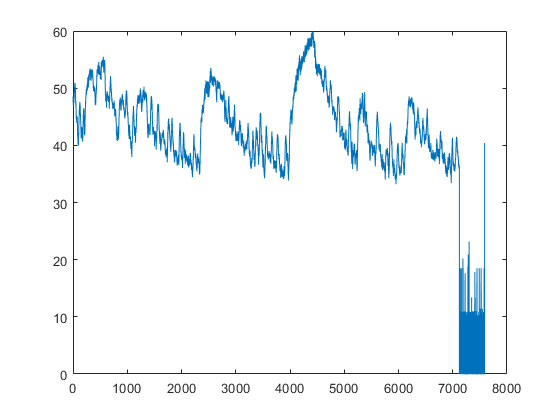

figure
plot (v26a.pupil)

### Extract %FOV active

Trying with 'out'

dir = 'C:\Users\camer\Box\CMH\.repos\pfc\data\by.trial\v26\b\121219_V26_59um_2x-000_video\'

dir = 'C:\Users\camer\Box\CMH\.repos\pfc\data\by.trial\v26\b\121219_V26_59um_2x-000_video\'


out = readFts(dir)

     1

below
121219_V26_59um_2x-000_video_aqua


out = struct with fields:
                    dffMat: {[28×427 single]}
                     xSize: {[502]}
                     ySize: {[502]}
                     zSize: {[427]}
                  datNames: {'121219_V26_59um_2x-000_video_aqua'}
                  propGrow: {{1×28 cell}}
           propGrowOverall: {[28×4 double]}
    propSpeedPerFrameDArea: {{1×28 cell}}
         propSpeedPerFrame: {{1×28 cell}}
                       dff: {[0.7268 0.8116 0.7753 0.8296 0.7764 0.7031 14.8671 0.6790 0.9666 0.9908 7.9350 1.2588 3.8056 0.8336 0.8453 0.7019 1.0431 12.9010 0.7967 0.9657 0.6552 0.5375 2.7546 12.8019 0.9033 5.9996 3.8564 6.0551]}
               dffMaxFrame: {[28 33 29 28 24 28 12 240 66 29 321 23 289 32 266 268 20 22 35 33 258 21 422 310 259 412 336 374]}
                   dffRise: {[0.5558 3.8905 3.8905 4.4463 2.2231 1.1116 0.5558 1.1116 3.8905 1.1116 3.8905 1.6674 1.6674 0.5558 2.7789 3.3347 0.5558 1.6674 1.6674 1.1116 0.5558 1.1116 1.6674 0.5558 7.7810 0.5558 1.1116 1.1116

Set resoltions etc

spRes = 0.80718154623606

spRes = 0.8072

tres = 0.55578697729921

tres = 0.5558

detection 

    A = length(out.datNames);
    clear bursts burstStats

    for jj = 1:A
        
        %% Frame size and video f length  
            frames = out.zSize{jj};
            xSize = out.xSize{jj};
            ySize = out.ySize{jj};
            zSize = frames;
    
        %% Absolute locations of all events
            clear aLocs aLocsB xLocs yLocs tLocs
            for i = 1:length(out.locAbs{jj})
                absLocsB = out.locAbs{jj};
                aLocs = absLocsB{i}; %single event
                [xLocs{i} yLocs{i} tLocs{i}] = (ind2sub([xSize ySize zSize], aLocs));
                xLocs{i} = xSize-xLocs{i};
            end
        
        %% Set Zero arrays for curve BW and sizeT -- what are these for?
                % What do these correspond to ... 
            curveBW = zeros(length(tLocs),frames);
            sizeT = zeros(length(tLocs),frames);
        
        

        %% Number of onsets per frame
            clear growthT
            growthT = zeros(length(tLocs),frames);
            for i = 1:length(tLocs) %#events
                clear uT %uT is always 2 frames shorter than fts.propGrow
                uT = unique(tLocs{i}); %time points of an event
                if ~isempty(uT)
                    minuT = min(uT); %just the first frame of an event
                    curveBW(i,minuT) = 1;
                    k=1;
                    for j =2:length(uT)
                        if nansum(out.propGrow{jj}{i}(j,:)) == 0
                            growthT(i,uT(k)) = 0;
                        else
                            growthT(i,uT(k)) = nansum(out.propGrow{jj}{i}(j,:));
                        end
                        k=k+1;
                    end
                end
            end
            
            numEvts = sum(curveBW,1);
            burstStats.numEvts{jj} = numEvts;
            growthEvts = sum(growthT,1);
            X = growthEvts(growthEvts > 0)';
            
            
            f = figure(jj);
            screen_size = get(0, 'ScreenSize');
            set(f, 'Position', ...
                [screen_size(3)/20 ...
                screen_size(4)/20 ...
                screen_size(3)*9/10 ...
                screen_size(4)*8.5/10]);
            
        
        %% Percent area with event activity
            clear allEvtLocs uLocs
            allEvtLocs = cell2mat(out.loc2D{jj}'); %%% extract all event locs
            uLocs = unique(allEvtLocs);
            
            

            
            numPix = length(uLocs); %number of pixels where an event occupied
            sizeT = zeros(length(tLocs),frames);
            
            for i = 1:length(tLocs)
                clear uT
                uT = unique(tLocs{i});

                if ~isempty(uT)

                    if length((out.pixelSizePerFrame{jj}{i}(1:end,1))) == length(uT)
                    
                        sizeT(i,uT) = ((out.pixelSizePerFrame{jj}{i}(1:end,1)) / (spRes^2));
                        
                    end
                end
            end
            

            
            sizeEvts = sum(sizeT,1);
            percEvts = (sizeEvts ./ numPix) * 100;
            burstStats.percEvts{jj} = percEvts;
        
        
    
        
        %% find burst periods: >1% %FOV, >25 frames apart, >25% max #events 
            thr = 1;
            [xPeaks,maxPkTimes] = findpeaks(percEvts,'MinPeakHeight',thr,'MinPeakDistance',25);
            
            pp = zeros(numel(xPeaks),2);  % 10%, 90% by start/end
            thrVec = [0.1];
        
        %% Baseline Detection
            % Baseline Number of Events
                    % Taking the mode of number of events that != 0. Having the mode
                    % = to zero will cause problems down the line
                    numEvts_mode =  numEvts(numEvts ~= 0);
                    base.numEvts =  mode(numEvts_mode);
                    
                % Baseline percEvts
                        % Taking baseline percEvts based on the frames with mode # of
                        % events
                    percEvts_mode = percEvts(numEvts == base.numEvts);
                    percEvts_mode_mean = mean(percEvts_mode);
                    base.percEvts = percEvts_mode_mean;
    end

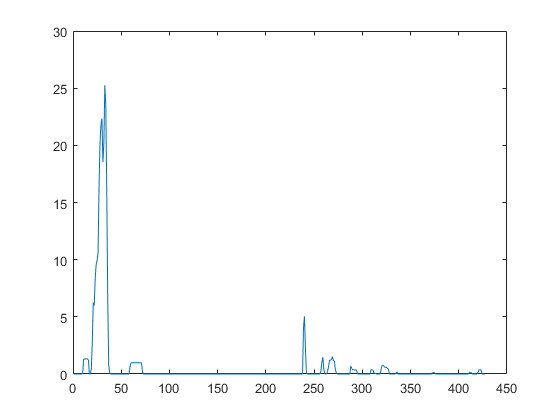

figure
    plot(percEvts)

percframetimes = 0:tres:237

percframetimes =          0    0.5558    1.1116    1.6674    2.2231    2.7789    3.3347    3.8905    4.4463    5.0021    5.5579    6.1137    6.6694    7.2252    7.7810    8.3368    8.8926    9.4484   10.0042   10.5600   11.1157   11.6715   12.2273   12.7831   13.3389   13.8947   14.4505   15.0062   15.5620   16.1178   16.6736   17.2294   17.7852   18.3410   18.8968   19.4525   20.0083   20.5641   21.1199   21.6757   22.2315   22.7873   23.3431   23.8988   24.4546   25.0104   25.5662   26.1220   26.6778   27.2336


percframetimes

percframetimes =          0    0.5558    1.1116    1.6674    2.2231    2.7789    3.3347    3.8905    4.4463    5.0021    5.5579    6.1137    6.6694    7.2252    7.7810    8.3368    8.8926    9.4484   10.0042   10.5600   11.1157   11.6715   12.2273   12.7831   13.3389   13.8947   14.4505   15.0062   15.5620   16.1178   16.6736   17.2294   17.7852   18.3410   18.8968   19.4525   20.0083   20.5641   21.1199   21.6757   22.2315   22.7873   23.3431   23.8988   24.4546   25.0104   25.5662   26.1220   26.6778   27.2336


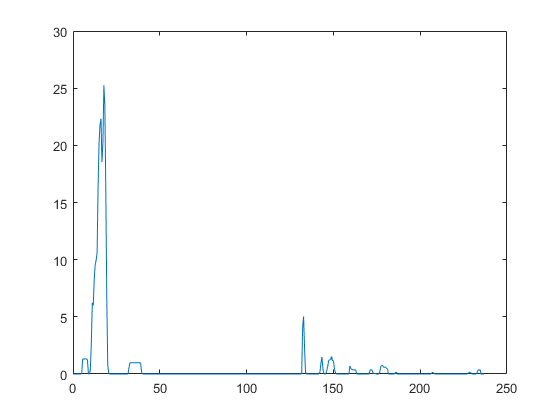

plot(percframetimes, percEvts)

pupilframetimes = 0.033333333333:0.0333333333333:252.95

pupilframetimes =     0.0333    0.0667    0.1000    0.1333    0.1667    0.2000    0.2333    0.2667    0.3000    0.3333    0.3667    0.4000    0.4333    0.4667    0.5000    0.5333    0.5667    0.6000    0.6333    0.6667    0.7000    0.7333    0.7667    0.8000    0.8333    0.8667    0.9000    0.9333    0.9667    1.0000    1.0333    1.0667    1.1000    1.1333    1.1667    1.2000    1.2333    1.2667    1.3000    1.3333    1.3667    1.4000    1.4333    1.4667    1.5000    1.5333    1.5667    1.6000    1.6333    1.6667


Try plotting all together

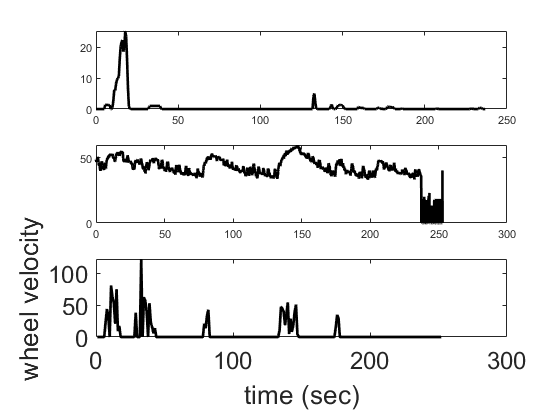

tiledlayout(3,1)

% top = perc fov
nexttile
plot(percframetimes, percEvts, 'LineWidth',2,'Color','k')


% mid = pupil
nexttile
plot (pupilframetimes, v26a.pupil, 'LineWidth',2,'Color','k')

% bottom = velocity
nexttile
plot(1:length(numbreaks),velocity, 'LineWidth',2,'Color','k')
ylabel('wheel velocity')
xlabel('time (sec)')
set(gca,'FontSize',18)

low pass filter the pupil data and fix error

pupilp = v26a.pupil

pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupil = figure

pupil =   Figure (LiveEditorRunTimeFigure) with properties:

      Number: 17
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [1440 918 560 420]
       Units: 'pixels'

  Show all properties


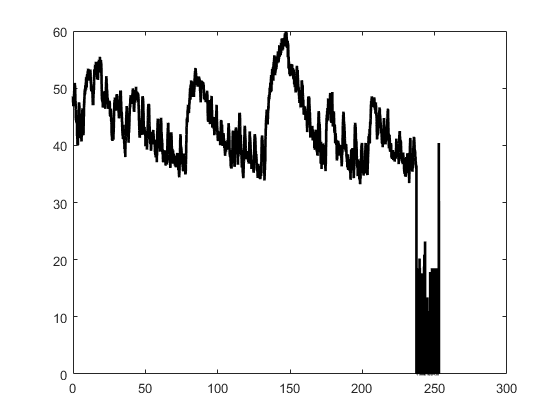

plot (pupilframetimes, pupilp, 'LineWidth',2,'Color','k')

for ii = 1:length(pupilp)
    if pupilp(ii) == 0
        pupilp(ii) = pupilp(ii-1)
    end
end

pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


pupilp =    47.6071
   48.5588
   48.3096
   47.3439
   47.8776
   46.8393
   47.4427
   47.4440
   47.7902
   47.3231


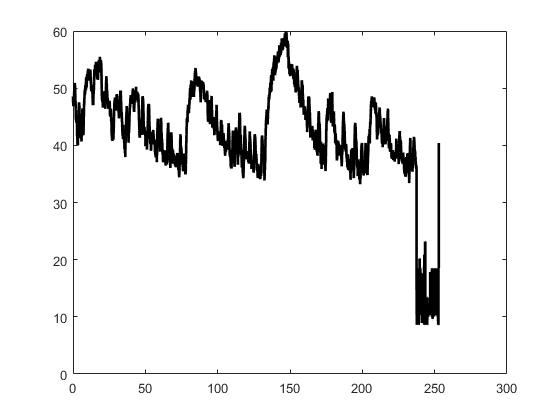


plot (pupilframetimes, pupilp, 'LineWidth',2,'Color','k')

pupilpl = lowpass(pupilp,0.00000000000000000000000000001)

pupilpl =    25.7278
   29.4042
   32.9321
   36.2245
   39.2083
   41.8284
   44.0502
   45.8605
   47.2666
   48.2943


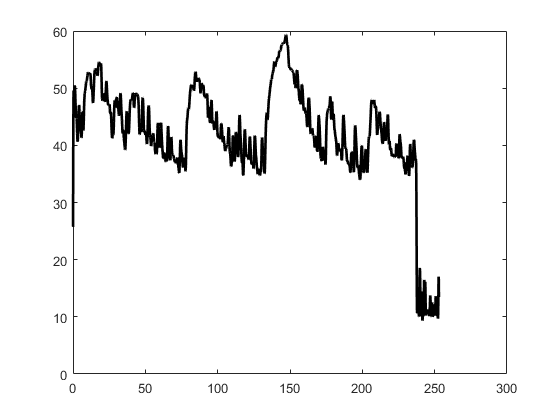

plot (pupilframetimes, pupilpl, 'LineWidth',2,'Color','k')

v26a.plot = tiledlayout(3,1)

v26a = struct with fields:
    pupil: [7588×1 double]
     plot: [1×1 TiledChartLayout]


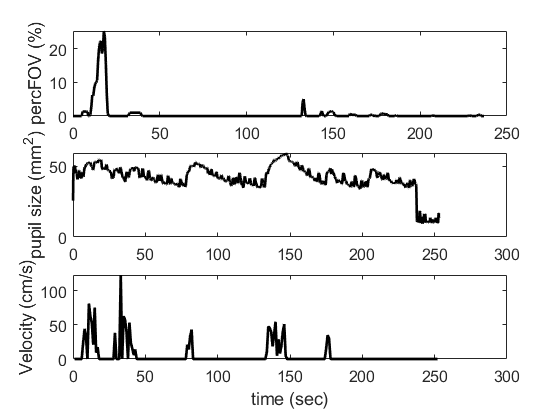


% top = perc fov
nexttile
plot(percframetimes, percEvts, 'LineWidth',2,'Color','k')
ylabel('percFOV (%)')
set(gca,'FontSize',12)

% mid = pupil
nexttile
plot (pupilframetimes, pupilpl, 'LineWidth',2,'Color','k')
ylabel('pupil size (mm^2)')
set(gca,'FontSize',12)

% bottom = velocity
nexttile
plot(1:length(numbreaks),velocity, 'LineWidth',2,'Color','k')
ylabel('Velocity (cm/s)')
xlabel('time (sec)')
set(gca,'FontSize',12)

v26.b